% Define suspension system equation

% Define specified parameters
c = 1.5*10^3 

c = 1500

k = 1.5*10^4

k = 15000

m = 3.6*10^3

m = 3600


y0 = 0.3

y0 = 0.3000


% Define calculated values
n = c/(2*m)

n = 0.2083

hpk = k/m

hpk = 4.1667

com = c^2 / (4*m^2)

com = 0.0434


assert(hpk > com)

p = sqrt(hpk - com)

p = 2.0306

% Define function
syms t

susp_fun(t) = exp(-n*t)* y0 * (cos(p*t) + (n/p)*sin(p*t))

$$susp\_fun(t) = \frac{3\,{\mathrm{e}}^{-\frac{5\,t}{24}}\,\left(\cos\left(\frac{5\,\sqrt{95}\,t}{24}\right)+\frac{\sqrt{95}\,\sin\left(\frac{5\,\sqrt{95}\,t}{24}\right)}{95}\right)}{10}$$

% Plot graph
syms x1
x1 = 0:0.01:10

x1 =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


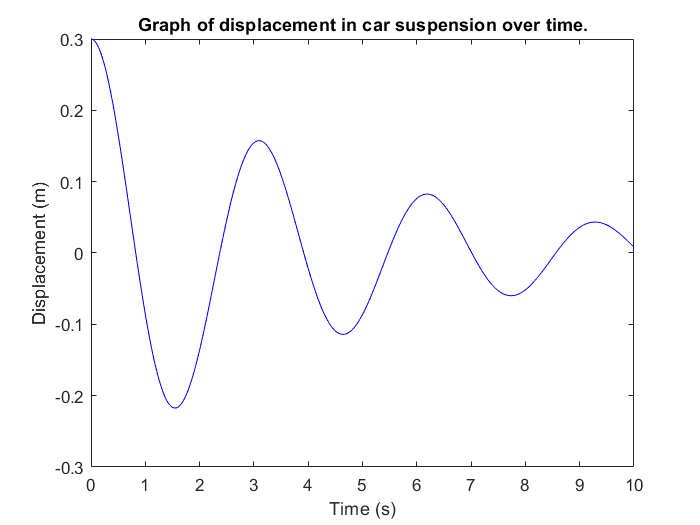

plot(x1,susp_fun(x1),'-b')
hold on

xlabel("Time (s)")
ylabel("Displacement (m)")
title("Graph of displacement in car suspension over time.")

syms x2
f(x2) = x2^3 - 5*x2^2-2*x2+10

$$f(x2) = {x_{2}}^{3}-5\,{x_{2}}^{2}-2\,x_{2}+10$$

c = f(10)

$$c = 490$$

a = diff(f,2)

$$a(x2) = 6\,x_{2}-10$$


fg = double(find_root(0.1,susp_fun,0.001))

$$y = \begin{array}{l} \frac{3\,{\mathrm{e}}^{-\frac{5}{24\,\sigma_{2}}-\frac{1}{48}}\,\left(\cos\left(\sigma_{1}\right)+\frac{\sqrt{95}\,\sin\left(\sigma_{1}\right)}{95}\right)}{10}\\ \mathrm{where}\\ \sigma_{1}=\frac{5\,\sqrt{95}\,\left(\frac{1}{\sigma_{2}}+\frac{1}{10}\right)}{24}\\ \sigma_{2}=\frac{\frac{{\mathrm{e}}^{-\frac{1}{48}}\,\sigma_{5}}{8}-\frac{5\,{\mathrm{e}}^{-\frac{1}{48}}\,\sigma_{6}}{384}+\frac{3\,{\mathrm{e}}^{-\frac{1}{48}}\,\left(\frac{2375\,\sigma_{8}}{576}+\frac{25\,\sqrt{95}\,\sigma_{7}}{576}\right)}{10}}{\frac{\sigma_{4}}{8}-\frac{\sigma_{3}}{5}}+\frac{10\,{\mathrm{e}}^{1/48}\,\left(\frac{\sigma_{4}}{16}-\frac{\sigma_{3}}{10}\right)}{3\,\sigma_{6}}\\ \sigma_{3}=3\,{\mathrm{e}}^{-\frac{1}{48}}\,\sigma_{5}\\ \sigma_{4}={\mathrm{e}}^{-\frac{1}{48}}\,\sigma_{6}\\ \sigma_{5}=\frac{5\,\sigma_{8}}{24}-\frac{5\,\sqrt{95}\,\sigma_{7}}{24}\\ \sigma_{6}=\sigma_{8}+\frac{\sqrt{95}\,\sigma_{7}}{95}\\ \sigma_{7}=\sin\left(\frac{\sqrt{95}}{48}\right)\\ \sigma_{8}=\cos\left(\frac{\sqrt{95}}{48}\right) \end{array}$$

x = 0.6615

y = 0.0851

x = 0.8210

y = 0.0015

x = 0.8239

y = 9.4767e-09

fg = 0.8239

% Experimental data
time = [2.6:0.05:3.1]

time =     2.6000    2.6500    2.7000    2.7500    2.8000    2.8500    2.9000    2.9500    3.0000    3.0500    3.1000


displacement = [0.074, 0.094, 0.106, 0.113, 0.127, 0.145, 0.145, 0.148, 0.154, 0.162, 0.158]

displacement =     0.0740    0.0940    0.1060    0.1130    0.1270    0.1450    0.1450    0.1480    0.1540    0.1620    0.1580


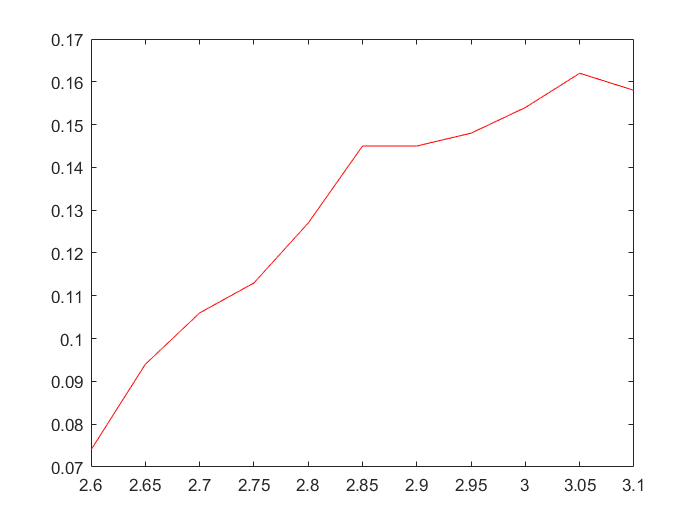


figure
plot(time,displacement,'-r')


x2 = [0,1,2,3,5]

x2 =      0     1     2     3     5


y2 = [0,1.4, 2.2, 3.5, 4.4]

y2 =          0    1.4000    2.2000    3.5000    4.4000



% mean_displacement = mean(displacement)
% total_sum_of_squares = power(displacement - mean_displacement,2)

% [a,b] = linear_regression(time,displacement) 

[a,b] = linear_regression(x2,y2) 

x_sum = 11

y_sum = 11.5000

xy_sum = 38.3000

x_square_sum = 39

N = 5

denom = 74

a = 0.3676

b = 0.8784

a = 0.3676

b = 0.8784


lin = a+b*time

lin =     2.6514    2.6953    2.7392    2.7831    2.8270    2.8709    2.9149    2.9588    3.0027    3.0466    3.0905


[R,e] = calc_md_and_standard_error(displacement,lin)

mean_y = 0.1296

N = 11

R = 0.9999

e = 2.3511

R = 0.9999

e = 2.3511



% residual_sum_of_squares = 


function [R,e] = calc_md_and_standard_error(y,g)
    assert(length(y) == length(g))
    
    mean_y = mean(y)
    N = length(y)
    
    R = 1 - sum((y - mean_y).^2) / sum((y - g).^2)
    e = sqrt( sum((y-g).^2 )/ N-2 )

end
function [a,b] = linear_regression(x,y)
    assert(length(x) == length(y))
    
    x_sum = sum(x)
    y_sum = sum(y)
    xy_sum = sum(x.*y)
    x_square_sum = sum(x.^2)
    N = length(x)
    
    denom = N*x_square_sum - x_sum^2
    
    a = (y_sum*x_square_sum - xy_sum*x_sum) / denom
    b = (N*xy_sum - y_sum*x_sum) / denom 

end
function x = find_root(x0,func,error)
    assert(error > 0)
    
    x = newton_rhapson_2(x0,func);
    y = func(x)
    
    
    while abs(y) > error
        x = double(newton_rhapson_2(x,func))
        y = double(func(x))
    end
end

function x = newton_rhapson_2(x0,func)
    der_func = diff(func);
    sec_der_func  = diff(func,2);
    
    slope = der_func(x0);
    der_slope = sec_der_func(x0);
    
    x = x0 + (der_slope/(2*slope) - slope/func(x0))^-1;
end